x=load("result\x.txt");
u=load('result\u.txt');
u_anal=load('result\u_anal.txt');
params = readtable("result\params.txt");
t=params.dt*(0:params.nsteps);
noise_type_str = ["NO NOISE", "BIT FLIP", "DEPOLARIZING", "DEPHASING", "AMPLITUDE DAMPING"];
name = strcat(noise_type_str(params.noise_type+1), num2str(params.noise_p),...
    '_lambda',num2str(params.lambda),...
    '_offset',num2str(params.offset),...
    '_dt', num2str(params.dt),...
    '_nqubits',num2str(params.nqubits),...
    '_initCond',num2str(params.init_cond))

name = "DEPHASING0.001_lambda2_offset2_dt0.005_nqubits9_initCond1"

save(strcat('DATA/MAT_',name,'.mat'),"t","u","u_anal","x", "params");

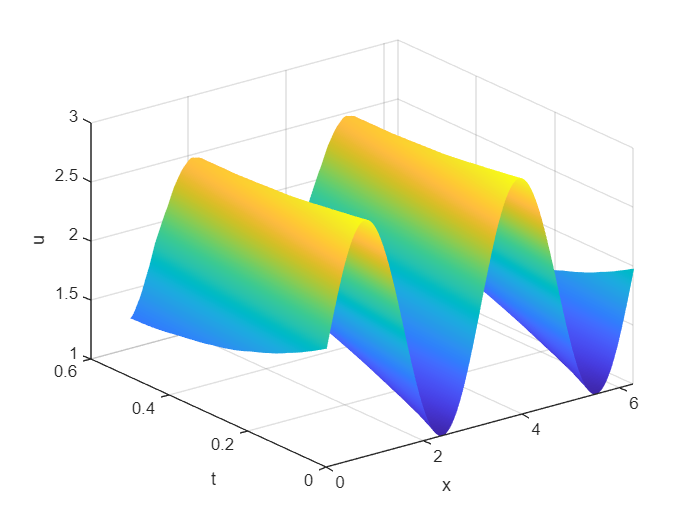

[X,T]=meshgrid(x,t);
surf(X,T,abs(u))
xlabel('x')
ylabel('t')
zlabel('u')
shading interp
savefig(gcf, strcat('FIG/Data/DAT_', name,'.fig'))
exportgraphics(gcf, strcat('FIG/Data/DAT_', name,'.pdf'));